clear all
close all

# DATOS DE LA MÁQUINA ASÍNCRONA TRIFÁSICA

p = 6/2;            %Pares de polos
M = 304.3e-3;       %Inductancia mutua
f = 50;             %Frecuencia red
V = 380/sqrt(3);    %Alimentacion red 380V, conexion Y
R1 = 0.7;           %Resistencia estator
L1 = 9.1e-3;        %Inductancia estator
R2 = 0.75;          %Dato resistencia desde el primario
L2 = 9.5e-3;        %Dato inductancia desde el primario

%Obtención de los parametros restantes
X1 = 2*pi*f*L1;     %Reactancia estator
X2 = 2*pi*f*L2;     %Reactancia rotor cuando no gira
N1 = 60*f/p;        %Velocidad sincronismo


# **Ejercicio 3.1**

# **Apartado 3.1.A: modo motor**

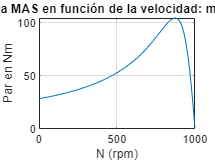

a = 0;

for iter = 0:1:1000
    a = a + 1;

    s(a) = (N1 - iter)/N1;

    I0(a) = V/(2*pi*f*M);                             %Corriente magnetizacion
    I2(a) = V/(sqrt((R1 + (R2/s(a)))^2 + (X1 + X2)^2));  %Corriente estator
    I1(a) = I0(a) + I2(a);      %Corriente total = Corriente estator + corriente magnetizacion
    
    Ta(a) = (3*R2*I2(a)^2)/(2*pi*(N1/60)*s(a));          %Par
end

Na = 0:1:1000;

%Grafica velocidad - par
plot(Na,Ta);
grid;
title('Par de la MAS en función de la velocidad: modo motor');
xlabel('N (rpm)');
ylabel('Par en Nm');

# **Apartado 3.1.B: analisis cargas mecanicas**

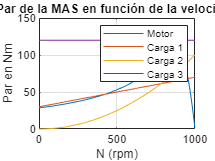

l = 0;
for l = 1:length(Na)
    T1b(l) = (Na(l)/25) + 30;     %Carga 1
    T2b(l) = 10e-5 * Na(l)^2;     %Carga 2
    T3b(l) = 120;                 %Carga 3
end
%Grafica velocidad - par conjunta
plot(Na,Ta,Na,T1b,Na,T2b,Na,T3b)
grid
title('Par de la MAS en función de la velocidad');
xlabel('N (rpm)');
ylabel('Par en Nm');
legend('Motor','Carga 1','Carga 2','Carga 3');

# **Apartado 3.1.C: modo generador**

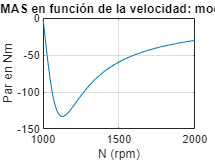

%Modo generador: de N1 a 2*N1
m = 0;

for iter = 1000:1:2000
    m = m + 1;
    s(m) = (N1 - iter)/N1;
    
    I0c(m) = V/(2*pi*f*M);                             %Corriente magnetizacion
    I2c(m) = V/(sqrt((R1 + (R2/s(m)))^2 + (X1 + X2)^2));  %Corriente estator
    I1c(m) = I0c(m) + I2c(m);      %Corriente total = Corriente estator + corriente magnetizacion

    Tc(m) = (3*R2*I2c(m)^2)/(2*pi*(N1/60)*s(m));  %Par

end
Nc = 1000:1:2000;

%Grafica velocidad - par
plot(Nc,Tc)
grid
title('Par de la MAS en función de la velocidad: modo generador');
xlabel('N (rpm)');
ylabel('Par en Nm');

# **Apartado 3.1.D: modo freno**

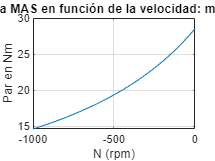

%Modo freno: -N1 a 0

n = 0;

for iter = -1000:1:0
    n = n + 1;

    s(n) = (N1 - iter)/N1;

    I0d(n) = V/(2*pi*f*M);                                 %Corriente magnetizacion
    I2d(n) = V/(sqrt((R1 + (R2/s(n)))^2 + (X1 + X2)^2));  %Corriente estator
    I1d(n) = I0d(n) + I2d(n);      %Corriente total = Corriente estator + corriente magnetizacion

    Td(n) = (3*R2*I2d(n)^2)/(2*pi*(N1/60)*s(n));          %Par
end

Nd = -1000:1:0;

%Grafica velocidad - par
plot(Nd,Td) 
grid
title('Par de la MAS en función de la velocidad: modo freno');
xlabel('N (rpm)');
ylabel('Par en Nm');

# **Unificar las graficas**

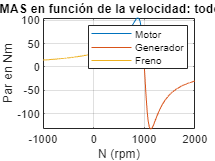

plot(Na,Ta,Nc,Tc,Nd,Td)
grid
title('Par de la MAS en función de la velocidad: todos los modos');
xlabel('N (rpm)');
ylabel('Par en Nm');
legend('Motor','Generador','Freno');

# **Ejercicio 3.2**

# **Apartado 3.2.A: variacion de la resistencia rotorica**                      

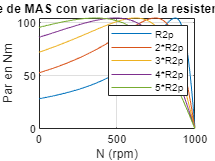


b = 0;

for iter = 1:1:5

    R2a = R2*iter;

    for s = 0:0.001:1
        b = b + 1;

        I2a(b) = V/(sqrt((R1 + (R2a/s))^2 + (X1 + X2)^2));       %Corriente del estator

        Na(b) = N1*(1 - s);                                      %Velocidad del rotor
        Ta(b) = (3*R2a*I2a(b)^2)/(2*pi*(N1/60)*s);               %Par
    end
    b = 0;
    plot (Na,Ta) 
    grid
    xlabel("N (rpm)")
    ylabel("Par en Nm")
    title("Arranque de MAS con variacion de la resistencia rotorica")
    hold on
end
legend("R2p","2*R2p","3*R2p","4*R2p","5*R2p")
hold off

# **Ejercicio 3.3**

# **Apartado 3.3.1: controlar la tension aplicada al estator**

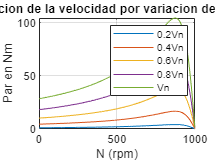

c = 0;

for iter2 = 0.2:0.2:1

    Vr = V*iter2;

    for s = 0:0.001:1
        c = c + 1;

        I2a(c) = Vr/(sqrt((R1 + (R2/s))^2 + (X1 + X2)^2));       %Corriente del estator

        Na(c) = N1*(1 - s);                                      %Velocidad del rotor
        Ta(c) = (3*R2*I2a(c)^2)/(2*pi*(N1/60)*s);               %Par
    end
    c = 0;
    plot (Na,Ta) 
    grid
    xlabel("N (rpm)")
    ylabel("Par en Nm")
    title("Regulacion de la velocidad por variacion de la tension")
    hold on
end
legend("0.2Vn","0.4Vn","0.6Vn","0.8Vn","Vn")
hold off

# **Apartado 3.3.2: variacion de frecuencia**

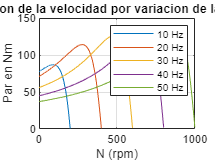

index = 0;
a = 0;

for fc = 10:10:50
    a = a + 1;

    N1c(a) = (60*fc)/p;
    Vc(a) = 5*fc;
    Xc(a) = (L1 + L2)*2*pi*fc;

    for s = 0:0.001:1
        index = index + 1;

        I2b(index) = Vc(a)/(sqrt((R1 + (R2/s))^2 + (Xc(a)).^2));       %Corriente del estator

        Nb(index) = N1c(a)*(1 - s);                                      %Velocidad del rotor
        Tb(index) = (3*R2*I2b(index)^2)/(2*pi*(N1c(a)/60)*s);               %Par
    end
    index = 0;
    a = 0;

    plot (Nb,Tb);
    grid;
    xlabel("N (rpm)")
    ylabel("Par en Nm")
    title("Regulacion de la velocidad por variacion de la frecuencia")
    hold on;

end
legend("10 Hz","20 Hz","30 Hz","40 Hz","50 Hz")
hold off;


%Obtencion de la smax y Tmax

a = 0;

for fc = 10:10:50
    a = a + 1;

    N1c(a) = (60*fc)/p;
    Vc(a) = 5*fc;
    Xc(a) = (L1 + L2)*2*pi*fc;

    smax(a) = R2/sqrt(R1^2 + (Xc(a))^2);
    I2b(a) = Vc(a)/(sqrt((R1 + (R2/smax(a)))^2 + (Xc(a)).^2));
    Tmax(a) = (3*R2*I2b(a)^2)/(2*pi*(N1c(a)/60)*smax(a));
end

smax

smax =     0.5505    0.3074    0.2098    0.1587    0.1274


Tmax

Tmax =    86.8212  114.0473  125.6423  131.9739  135.9495
